% to run this simulation, you need to run the "system_parameter.mlx" first
run("system_parameter.mlx")

m = 16.5000

W = 162

b = 162

L = 0.7615

d = 0.0220

Ix = 0.1280

Iy = 0.9410

Iz = 0.9716

Ixy = 0

Ixz = 0

Iyz = 0

xG = 0

yG = 0

zG = 0

xB = 0

yB = 0

zB = -0.0100

BGz = 0.0100

Yvt = 0.1670

Yht = 0.1670

Xudot = -6.4800

Xvdot = 0

Xwdot = 0

Yvdot = -19.2700

Ywdot = 0

Zudot = 0

Zwdot = -26.3900

Xpdot = 0

Xqdot = 0

Xrdot = 0

Ypdot = 0

Yqdot = 0

Yrdot = -0.1200

Zpdot = 0

Zqdot = -2.2000

Zrdot = 0

Kvdot = 0

Mudot = 0

Mwdot = -0.9400

Nvdot = 0.7200

Kpdot = -2.2000

Kqdot = 0

Krdot = 0

Mqdot = 0.5600

Mrdot = 0

Npdot = 0

Nrdot = -0.4800

Xu = -20.4000

Yv = -13.5100

Zw = -42.8800

Yp = 0

Yr = -9.3900

Zq = -17.0800

Kv = 0

Mw = -12.4100

Nv = 4.3100

Kp = -17.0800

Kr = 0

Mq = -6.0300

Np = 0

Nr = -1.5500

Xuu = -18.2000

Yuv = 0

Yvv = -34.2500

Zuw = 0

Zww = -87.3300

Yur = 0

Yvr = 0

Yrv = 111.8700

Zuq = 0

Muw = 0

Nuv = 0

Nvv = 0

Muq = 0

Nur = 0

Nvr = 0

Nrv = 0

Yrr = 0

Kpp = -5

Mqq = -5

Nrr = -8.2400

m11 = 22.9800

m22 = 35.7700

m33 = 42.8900

m44 = 2.3280

m55 = 0.3810

m66 = 1.4516

Du = 0

Dv = 0

Dw = 0

Dp = 0

Dq = 0

Dr = 0

% 3 symmetry planes
% M(nu)
M = diag([m11, m22, m33, m44, m55, m66])

M =    22.9800         0         0         0         0         0
         0   35.7700         0         0         0         0
         0         0   42.8900         0         0         0
         0         0         0    2.3280         0         0
         0         0         0         0    0.3810         0
         0         0         0         0         0    1.4516



% linearized model with VP P=I and low speed applications(nu=0) Cnu=0, Dn=0, Dnu=D 
P = eye(6,6)

P =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Cnu = zeros(6)

Cnu =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Dnu = -diag([Xu, Yv, Zw, Kp, Mq, Nr])

Dnu =    20.4000         0         0         0         0         0
         0   13.5100         0         0         0         0
         0         0   42.8800         0         0         0
         0         0         0   17.0800         0         0
         0         0         0         0    6.0300         0
         0         0         0         0         0    1.5500


Geta = diag([0, 0, 0, BGz*W, BGz*W, 0]) 

Geta =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    1.6200         0         0
         0         0         0         0    1.6200         0
         0         0         0         0         0         0



% A
A = [-inv(M)*(Cnu+Dnu)  -inv(M)*Geta;
            P               zeros(6)]

A =    -0.8877         0         0         0         0         0         0         0         0         0         0         0
         0   -0.3777         0         0         0         0         0         0         0         0         0         0
         0         0   -0.9998         0         0         0         0         0         0         0         0         0
         0         0         0   -7.3368         0         0         0         0         0   -0.6959         0         0
         0         0         0         0  -15.8268         0         0         0         0         0   -4.2520         0
         0         0         0         0         0   -1.0678         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0    1.00


% B
B = [inv(M)  ;
     zeros(6)]

B =     0.0435         0         0         0         0         0
         0    0.0280         0         0         0         0
         0         0    0.0233         0         0         0
         0         0         0    0.4296         0         0
         0         0         0         0    2.6247         0
         0         0         0         0         0    0.6889
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0



% C
C = eye(12, 12)

C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0



D = zeros(12,6)

D =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



% Gss
Gss = ss(A,B,C,D)

Gss =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1   -0.8877        0        0        0        0        0        0        0        0        0        0        0
   x2         0  -0.3777        0        0        0        0        0        0        0        0        0        0
   x3         0        0  -0.9998        0        0        0        0        0        0        0        0        0
   x4         0        0        0   -7.337        0        0        0        0        0  -0.6959        0        0
   x5         0        0        0        0   -15.83        0        0        0        0        0   -4.252        0
   x6         0        0        0        0        0   -1.068        0        0        0        0        0        0
   x7         1        0        0        0        0        0        0        0        0        0        0        0
   x8         0        1        0        0        0        0     

Gss.InputName = {'X', 'Y', 'Z', 'K', 'M', 'N'}

Gss =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1   -0.8877        0        0        0        0        0        0        0        0        0        0        0
   x2         0  -0.3777        0        0        0        0        0        0        0        0        0        0
   x3         0        0  -0.9998        0        0        0        0        0        0        0        0        0
   x4         0        0        0   -7.337        0        0        0        0        0  -0.6959        0        0
   x5         0        0        0        0   -15.83        0        0        0        0        0   -4.252        0
   x6         0        0        0        0        0   -1.068        0        0        0        0        0        0
   x7         1        0        0        0        0        0        0        0        0        0        0        0
   x8         0        1        0        0        0        0     

Gss.OutputName = {'u', 'v', 'w', 'p', 'q', 'r', 'x', 'y', 'z', 'phi', 'theta', 'psi'}

Gss =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1   -0.8877        0        0        0        0        0        0        0        0        0        0        0
   x2         0  -0.3777        0        0        0        0        0        0        0        0        0        0
   x3         0        0  -0.9998        0        0        0        0        0        0        0        0        0
   x4         0        0        0   -7.337        0        0        0        0        0  -0.6959        0        0
   x5         0        0        0        0   -15.83        0        0        0        0        0   -4.252        0
   x6         0        0        0        0        0   -1.068        0        0        0        0        0        0
   x7         1        0        0        0        0        0        0        0        0        0        0        0
   x8         0        1        0        0        0        0     

Gtf = tf(Gss)

Gtf =
 
  从输入 "X" 到输出...
        0.04352
   u:  ----------
       s + 0.8877
 
   v:  0
 
   w:  0
 
   p:  0
 
   q:  0
 
   r:  0
 
          0.04352
   x:  --------------
       s^2 + 0.8877 s
 
   y:  0
 
   z:  0
 
   phi:  0
 
   theta:  0
 
   psi:  0
 
  从输入 "Y" 到输出...
   u:  0
 
        0.02796
   v:  ----------
       s + 0.3777
 
   w:  0
 
   p:  0
 
   q:  0
 
   r:  0
 
   x:  0
 
          0.02796
   y:  --------------
       s^2 + 0.3777 s
 
   z:  0
 
   phi:  0
 
   theta:  0
 
   psi:  0
 
  从输入 "Z" 到输出...
   u:  0
 
   v:  0
 
        0.02332
   w:  ----------
       s + 0.9998
 
   p:  0
 
   q:  0
 
   r:  0
 
   x:  0
 
   y:  0
 
       0.02332
   z:  -------
       s^2 + s
 
   phi:  0
 
   theta:  0
 
   psi:  0
 
  从输入 "K" 到输出...
   u:  0
 
   v:  0
 
   w:  0
 
              0.4296 s
   p:  ----------------------
       s^2 + 7.337 s + 0.6959
 
   q:  0
 
   r:  0
 
   x:  0
 
   y:  0
 
   z:  0
 
                 0.4296
   phi:  ----------------------
    

% Unforced Response
% 1. limited by the vertical dimension of vehicle(small BGz), the oscillation of roll and pitch angle and angular speed are very small 
% 2. under the assumption of neutral bouncy, the value of z doesn't recover
x0 = [1, 1, 1, 10*pi/180, 10*pi/180, 10*pi/180, 0, 0, 0, 0, 0, 0]

x0 =     1.0000    1.0000    1.0000    0.1745    0.1745    0.1745         0         0         0         0         0         0


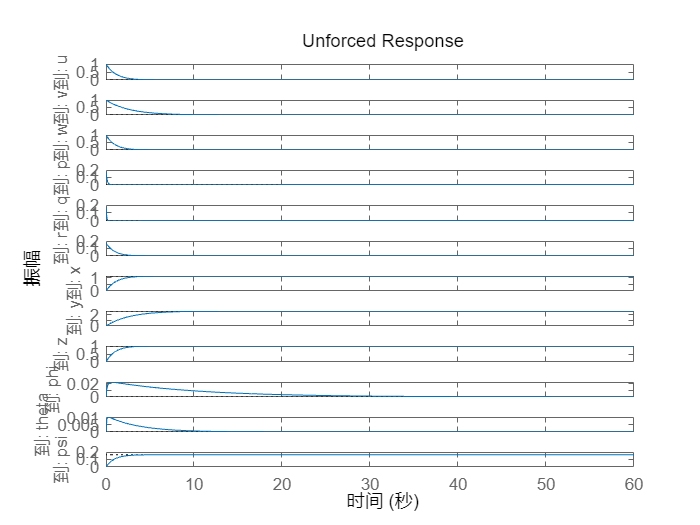

figure
initial(Gss, x0)
title('Unforced Response')

% Step Response and Bode Plot
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
xplot_ylabel = ["u (m/s)" "v (m/s)" "w (m/s)" "p (deg/s)" "q (deg/s)" "r (deg/s)" "x (m)" "y (m)" "z (m)" "phi (deg)" "theta (deg)" "psi (deg)"]

xplot_ylabel = 1×12 string 数组
    "u (m/s)"    "v (m/s)"    "w (m/s)"    "p (deg/s)"    "q (deg/s)"    "r (deg/s)"    "x (m)"    "y (m)"    "z (m)"    "phi (deg)"    "theta (deg)"    "psi (deg)"


xplot_title = ["Surge" 'Sway' 'Heave' 'Roll Rate' 'Pitch Rate' 'Yaw Rate' 'Axial' 'Lat' 'Depth' 'Roll' 'Pitch' 'Yaw']

xplot_title = 1×12 string 数组
    "Surge"    "Sway"    "Heave"    "Roll Rate"    "Pitch Rate"    "Yaw Rate"    "Axial"    "Lat"    "Depth"    "Roll"    "Pitch"    "Yaw"


xbode = ["Surge" 'Sway' 'Heave' 'Roll' 'Pitch' 'Yaw']

xbode = 1×6 string 数组
    "Surge"    "Sway"    "Heave"    "Roll"    "Pitch"    "Yaw"


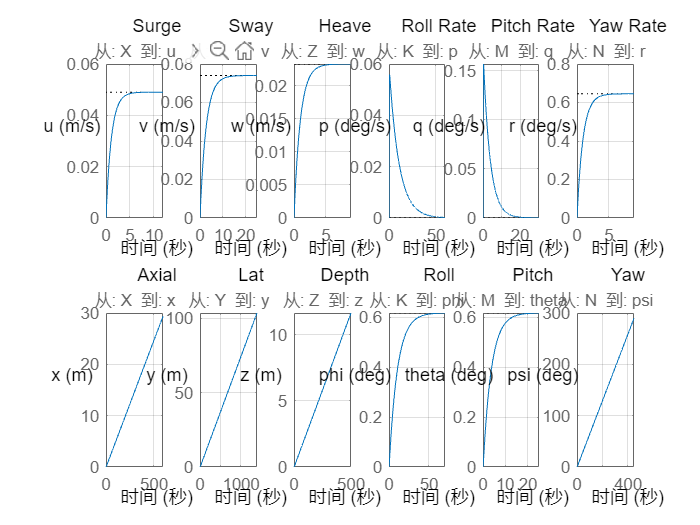

% subplot contrast 
figure
hold on
for i = 1:6

    subplot(2,6,i)
    step(Gtf(i,i))% 2-order overdamped system
    ylabel(xplot_ylabel(i),'rotation',0)
    title(xplot_title(i))
    grid on

    subplot(2,6,i+6)
    step(Gtf(i+6,i))
    ylabel(xplot_ylabel(i+6),'rotation',0)
    title(xplot_title(i+6))
    grid on
end
hold off

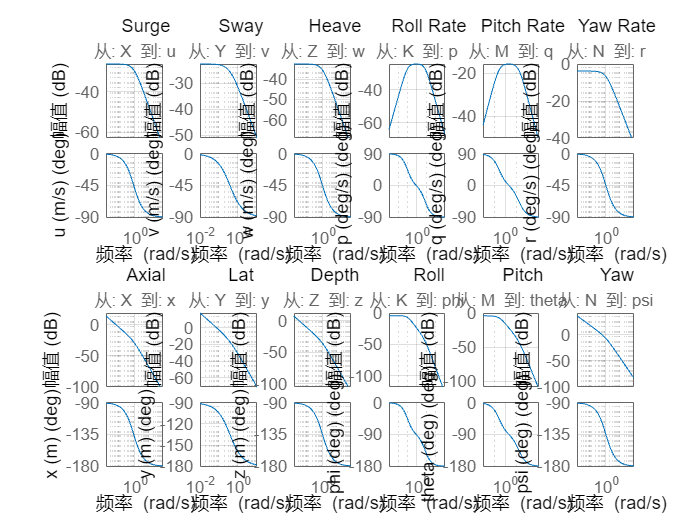


figure;  
hold on;
for i = 1:6
    subplot(2,6,i)
    bode(Gtf(i,i))
    ylabel(xplot_ylabel(i),'rotation',0)
    title(xplot_title(i))
    grid on
    
    subplot(2,6,i+6)
    bode(Gtf(i+6,i)) 
    ylabel(xplot_ylabel(i+6),'rotation',0)
    title(xplot_title(i+6))
    grid on
end
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% summary plot    
% figure
% hold on 
% for i = 1:6
%     step(Gtf(i,i), 0:0.01:4)% 2-order overdamped system
%     step(Gtf(i+6,i), 0:0.01:4)
%     title('Step Response')
%     grid on   
% end
% legend('u', 'v', 'w', 'p','q', 'r', 'x', 'y', 'z', 'phi', 'theta', 'psi')
% hold off
% 
% figure
% hold on 
% for i = 1:6
%     bode(Gtf(i,i))
%     bode(Gtf(i+6,i))
%     grid on
% end
% legend('u', 'v', 'w', 'p','q', 'r', 'x', 'y', 'z', 'phi', 'theta', 'psi')
% hold off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% separate contrast
% for i = 1:6
%     figure;  
%     hold on;
%     
%     step(Gtf(i,i), 0:0.01:4);  
%     ylabel(xplot_ylabel(i),'rotation',0)
%     step(Gtf(i+6,i), 0:0.01:4);  
%     ylabel(xplot_ylabel(i+6),'rotation',0)
%     title('Step Response');
%     grid on;
%     
%     hold off;
% end

% for i = 1:6
%     figure;  
%     hold on;
% 
%     bode(Gtf(i,i));  
%     bode(Gtf(i+6,i));
%     title(xplot_title(i))
%     
%     grid on;
%     hold off;
% end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% H infity Robust Control 
WP = tf([0.8],[100 1])

WP =
 
     0.8
  ---------
  100 s + 1
 
Continuous-time transfer function.



Wu = 0

Wu = 0

WT = tf([0 10000],[0.1 0.001])

WT =
 
      10000
  -------------
  0.1 s + 0.001
 
Continuous-time transfer function.




[K,CL,gamma,info]=mixsyn(Gtf,WP,[],WT)

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15
   x1        -0.01  -1.259e-38  -1.464e-37  -2.267e-37   -2.13e-38   5.377e-38   2.509e-38  -1.458e-39   2.789e-38  -6.497e-38  -1.037e-37   7.315e-38   3.042e-32  -2.461e-32    2.66e-32
   x2   -2.506e-32       -0.01   2.538e-34  -7.942e-34   4.717e-34  -3.946e-33   3.526e-31   7.191e-32   2.882e-32   3.922e-33  -7.626e-33   1.179e-31   3.854e-33   1.172e-32   6.713e-33
   x3   -1.393e-31  -1.023e-31       -0.01  -5.217e-33   8.809e-33  -6.144e-33   -7.01e-32  -7.506e-31    1.74e-31   9.236e-33  -4.273e-32   3.742e-31   4.632e-32  -3.105e-31  -7.058e-32
   x4    3.012e-32   1.938e-32  -7.093e-33       -0.01  -4.856e-33   3.341e-33   2.006e-31  -5.199e-32   -8.16e-32  -7.323e-34   1.118e-32   -1.28e-30   2.935e-32  -1.776e-31  -3.103e-32
   x5   -1.043e-32  -7.019e-33   5.601e-35  -1.471e-

gamma = 1.0000e+07

info =   hinfINFO - 属性:

    gamma: 1.2870e+07
        X: [40×40 double]
        Y: [40×40 double]
       Ku: [6×40 double]
       Kw: [16×40 double]
       Lx: [40×12 double]
       Lu: [6×12 double]
     Preg: [42×22 ss]
       AS: [18×18 ss]



S = feedback(eye(12), Gss*K, -1)

S =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15
   x1      -0.8877           0           0           0           0           0           0           0           0           0           0           0    1.33e-18  -1.196e-21    6.21e-21
   x2            0     -0.3777           0           0           0           0           0           0           0           0           0           0   7.673e-21   8.937e-19    1.48e-22
   x3            0           0     -0.9998           0           0           0           0           0           0           0           0           0  -9.736e-20  -1.137e-20   6.424e-19
   x4            0           0           0      -7.337           0           0           0           0           0     -0.6959           0           0  -7.848e-20   1.398e-21   2.512e-21
   x5            0           0           0          

T = feedback(Gss*K, eye(12), -1)

T =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15
   x1      -0.8877           0           0           0           0           0           0           0           0           0           0           0    1.33e-18  -1.196e-21    6.21e-21
   x2            0     -0.3777           0           0           0           0           0           0           0           0           0           0   7.673e-21   8.937e-19    1.48e-22
   x3            0           0     -0.9998           0           0           0           0           0           0           0           0           0  -9.736e-20  -1.137e-20   6.424e-19
   x4            0           0           0      -7.337           0           0           0           0           0     -0.6959           0           0  -7.848e-20   1.398e-21   2.512e-21
   x5            0           0           0          

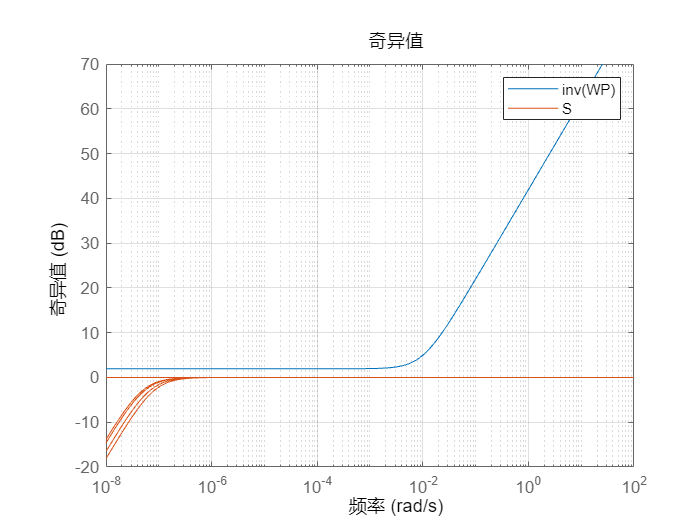


clf
sigma(inv(WP), S)
legend('inv(WP)', 'S')
grid on

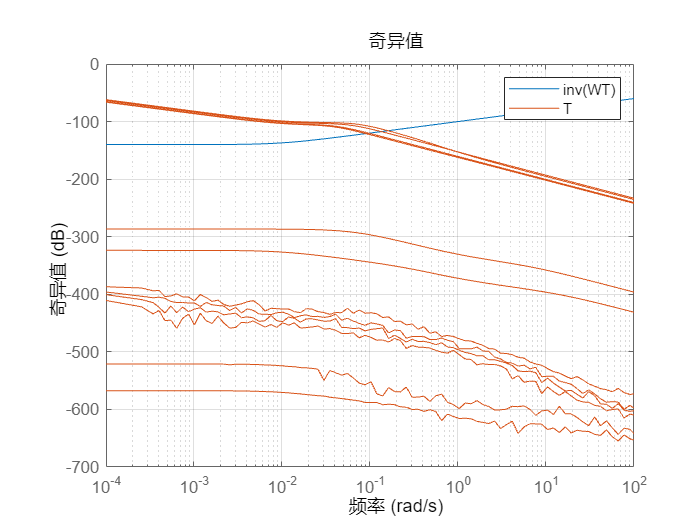

sigma(inv(WT), T)
legend('inv(WT)', 'T')
grid on



% xplot_title = ["Surge" 'Sway' 'Heave' 'Roll Rate' 'Pitch Rate' 'Yaw Rate' 'Axial' 'Lat' 'Depth' 'Roll' 'Pitch' 'Yaw']
% S_plot = ["S1" "S2" "S3" "S4" "S5" "S6" "S7" "S8" "S9" "S10" "S11" "S12" ]
% T_plot = ["T1" "T2" "T3" "T4" "T5" "T6" "T7" "T8" "T9" "T10" "T11" "T12" ]
% WP = [tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1]) tf([100],[500 1])]
% Wu = [tf([0],[1]) tf([0],[1]) tf([0],[1]) tf([0],[1]) tf([0],[1]) tf([0],[1])]
% WT = [tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000]) tf([200 0],[1 1000])]

% for i = 1:6
% 
%     [K,CL,gamma,info]=mixsyn(Gtf(i,i),WP(i),[],WT(i))
%     S(i) = feedback(1, Gtf(i,i)*K, -1)
%     T(i) = feedback(Gtf(i,i)*K, 1, -1)
% 
%     figure
%     sigma(inv(WP(i)), S(i))
%     legend('inv(WP)', S_plot(i))
%     grid on
% 
%     figure
%     sigma(inv(WT(i)), T(i))
%     legend('inv(WT)', T_plot(i))
%     grid on
% 
% end

% for i = 1:6
%     [K,CL,gamma,info]=mixsyn(Gtf(i+6,i),WP(i+6),[],WT(i+6))
%     S(i+6) = feedback(1, Gtf(i,i)*K, -1)
%     T(i+6) = feedback(Gtf(i,i)*K, 1, -1)
%     
%     clf
%     figure
%     sigma(inv(WP(i+6)), S(i+6))
%     legend('inv(WP)', S_plot(i+6))
%     grid on
% 
%     figure
%     sigma(inv(WT(i+6)), T(i+6))
%     legend('inv(WT)', T_plot(i+6))
%     grid on
% 
% end

